# CIE Metamerism Index

Q: how to evaluate Mu, Mv shown in papers by Tommy Wei?

A: implement ISO 23605

12/11/2022

ciemeta = CIE_Metamers;

clf
hgcf = gcf;
set(hgcf,'Visible','on' )


## D50

td = tiledlayout(4,5,'TileSpacing','loose');
for material_no = 1:5
    nexttile
    hold on
    ciemeta.d50{material_no,1}.plot
    ciemeta.d50{material_no,2}.plot
    axis([370 780 0 1])
    %legend('Standard','Comparison','Location','northwest')
    ylabel('D50')
    title(material_no)
end

## D55

%clf
%td = tiledlayout(1,5,'TileSpacing','loose');
for material_no = 1:5
    nexttile
    hold on
    ciemeta.d55{material_no,1}.plot
    ciemeta.d55{material_no,2}.plot
    axis([370 780 0 1])
    ylabel('D55')
    title(material_no)
end

## D65

%clf
%td = tiledlayout(1,5,'TileSpacing','loose');
for material_no = 1:5
    nexttile
    hold on
    ciemeta.d65{material_no,1}.plot
    ciemeta.d65{material_no,2}.plot
    axis([370 780 0 1])
    ylabel('D65')
    title(material_no)
end

## D75

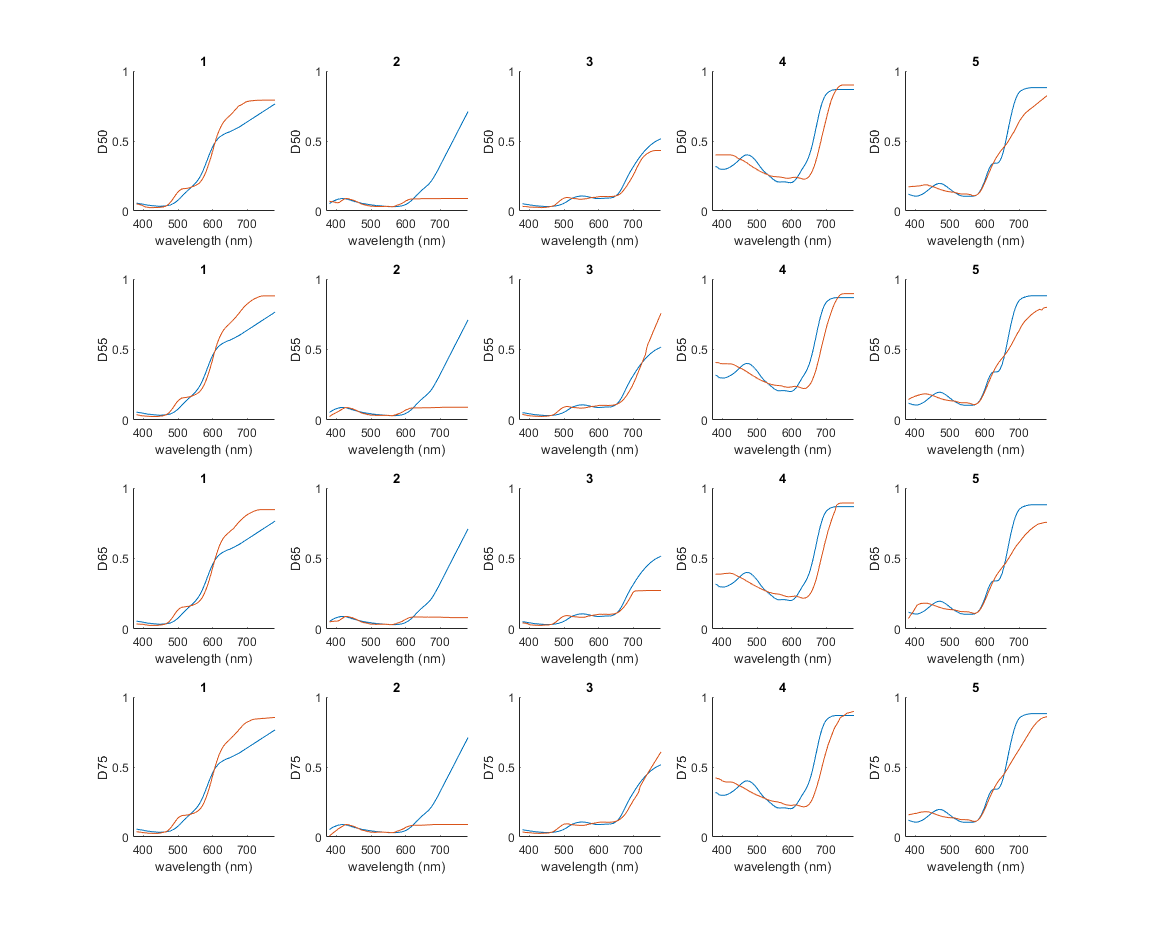

%clf
%td = tiledlayout(1,5,'TileSpacing','loose');
for material_no = 1:5
    nexttile
    hold on
    ciemeta.d75{material_no,1}.plot
    ciemeta.d75{material_no,2}.plot
    axis([370 780 0 1])
    ylabel('D75')
    title(material_no)
end
hgcf.Position = [509 162 1157 941];
saveas(hgcf,'finding.png')